clc,clear
% 数据导入
% 地块面积向量
S = readmatrix("E:\数学建模比赛\CUMCM2024Problems\C题\附件1.xlsx",'Sheet','乡村的现有耕地');
S = S(:,3);
S = [S; S(27:54)];

% 2023年耕种情况
x0 = readmatrix("E:\数学建模比赛\自处理数据\初始值.xlsx");
x0 = x0(2:83,3:end);
x0(isnan(x0)) = 0;

% 售价矩阵
P =  readmatrix("E:\数学建模比赛\自处理数据\预期售价.xlsx");    
P = P(:,3:end);
P(isnan(P)) = 0;
%P = [P P P P P P P];

% 预期销售量矩阵
D = readmatrix("E:\数学建模比赛\自处理数据\预期销售量(1).xlsx");
D = D(:,2:end);
D(isnan(D)) = 0;

%D = [D D D D D D D];

% 预期亩产量
q = readmatrix("E:\数学建模比赛\自处理数据\预期亩产量.xlsx");      
q = q(:,3:end);
q(isnan(q)) = 0;
%q = [q q q q q q q];

% 预期亩成本
C = readmatrix("E:\数学建模比赛\自处理数据\预期每亩成本.xlsx");
C = C(:,3:end);
C(isnan(C)) = 0;

% 确定各种参数的变化
% 小麦和玉米预期销售量的平均年增长率介于0.05~0.1之间
% 均匀分布
for i = 1:7
    r_D1(i) = (rand()+1)*0.05;
end

% 其他农作物的预期销售量相较于2023年有5%的上下浮动变化
% 均匀分布
for i = 1:7
    r_D2(i) = (rand()-0.5)*0.1;
end

% 农作物的亩产量每年会有10%的上下浮动
% 均匀分布
for i = 1:7
    r_q(i) = (rand()-0.5)*0.2;
end

% 农作物种植成本平均每年增长5%左右
% 正态分布
for i = 1:7
    r_C1(i) = randn()*0.003+0.05;
end

% 蔬菜种植成本平均每年增长5%左右
% 正态分布
for i = 1:7
    r_C2(i) = randn()*0.003+0.05;
end

% 食用菌除羊肚菌外销售价格大约每年下降1%~5%
% 均匀分布
for i = 1:7
    r_P1(i) = (4*rand()-5)*0.01;
end


% 羊肚菌销售价格每年下降幅度为5%
r_P2 = [-0.05 -0.05 -0.05 -0.05 -0.05 -0.05 -0.05];               %确定的数

% % %最坏情况
% rr = readmatrix("E:\数学建模比赛\自处理数据\最坏情况的变化率.xlsx");
% r_D1 = rr(1,:);
% r_D2 = rr(2,:);
% r_q = rr(3,:);
% r_C1 = rr(4,:);
% r_C2 = rr(5,:);
% r_P1 = rr(6,:);
% r_P2 = rr(7,:);



% % 最好情况
% rr = readmatrix("E:\数学建模比赛\自处理数据\最优情况的变化率.xlsx");
% r_D1 = rr(1,:);
% r_D2 = rr(2,:);
% r_q = rr(3,:);
% r_C1 = rr(4,:);
% r_C2 = rr(5,:);
% r_P1 = rr(6,:);
% r_P2 = rr(7,:);


% 确定7种变化在7年的最终变化情况
% 小麦和玉米预期销售量的平均年增长率介于0.05~0.1之间
Y_r_D1 = ones(7,7);
for i = 1:7
    Y_r_D1(i,7:-1:(8-i)) = r_D1(1:i)+1;
end
Y_r_D1 = Y_r_D1(:,1).* Y_r_D1(:,2).*Y_r_D1(:,3).* Y_r_D1(:,4).* Y_r_D1(:,5).* Y_r_D1(:,6).* Y_r_D1(:,7);


% 其他农作物的预期销售量相较于2023年有5%的上下浮动变化
Y_r_D2 = r_D2'+1;

% 农作物的亩产量每年会有10%的上下浮动
Y_r_q = r_q'+1;

% 农作物种植成本平均每年增长5%左右
Y_r_C1 = ones(7,7);
for i = 1:7
    Y_r_C1(i,7:-1:(8-i)) = r_C1(1:i)+1;
end
Y_r_C1 = Y_r_C1(:,1).* Y_r_C1(:,2).*Y_r_C1(:,3).* Y_r_C1(:,4).* Y_r_C1(:,5).* Y_r_C1(:,6).* Y_r_C1(:,7);

% 蔬菜销售价格平均每年增长5%左右
Y_r_C2 = ones(7,7);
for i = 1:7
    Y_r_C2(i,7:-1:(8-i)) = r_C2(1:i)+1;
end
Y_r_C2 = Y_r_C2(:,1).* Y_r_C2(:,2).*Y_r_C2(:,3).* Y_r_C2(:,4).* Y_r_C2(:,5).* Y_r_C2(:,6).* Y_r_C2(:,7);

% 食用菌除羊肚菌外销售价格大约每年下降1%~5%
Y_r_P1 = ones(7,7);
for i = 1:7
    Y_r_P1(i,7:-1:(8-i)) = r_P1(1:i)+1;
end
Y_r_P1= Y_r_P1(:,1).* Y_r_P1(:,2).*Y_r_P1(:,3).* Y_r_P1(:,4).* Y_r_P1(:,5).* Y_r_P1(:,6).* Y_r_P1(:,7);

% 羊肚菌销售价格每年下降幅度为5%
Y_r_P2 = ones(7,7);
for i = 1:7
    Y_r_P2(i,7:-1:(8-i)) = r_P2(1:i)+1;
end
Y_r_P2 = Y_r_P2(:,1).* Y_r_P2(:,2).*Y_r_P2(:,3).* Y_r_P2(:,4).* Y_r_P2(:,5).* Y_r_P2(:,6).* Y_r_P2(:,7);

D(:,[6,7]) = D(:,[6,7])* Y_r_D1(2);
% 其余农作物
D(:,[1:5 8:end]) = D(:,[1:5 8:end])* Y_r_D2(2);

% 还原预期销售量矩阵
D1 = [repmat(D(1,:), 6,1)
      repmat(D(2,:), 14,1)
      repmat(D(3,:),6,1)
      repmat(D(4,:),8,1)
      repmat(D(5,:),16,1)
      repmat(D(6,:),4,1)
      repmat(D(7,:),8,1)
      repmat(D(8,:),16,1)
      repmat(D(9,:),4,1)];
D1

D1 = 	1.0e+05 *

    0.2903         0         0    0.2399         0    0.7366    1.0358    0.2217         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2903         0         0    0.2399         0    0.7366    1.0358    0.2217         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.2903         0         0    0.2399         0    0.7366    1.0358    0.2217         0         0         0         0         0         0         0         0 

%模拟退火算法

[iterations, R_change,R, x1 ,x2 ,x3 ,x4 ,x5 ,x6 ,x7] = sa_tsp(S, x0, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2) 

---------------------------------------------------------------


iterations = 59113

R_change = 	1.0e+07 *

    3.3251    3.4274    3.1877    3.0925    3.2256    3.1168    3.2288    3.2750    3.1844    3.2193    3.2454    3.2228    3.3700    3.3377    3.3262    3.1880    3.2720    3.1285    3.2295    3.2939    3.1716    3.0443    3.2708    3.1715    3.2192    3.2443    3.2418    3.2975    3.1734    3.1095    3.3005    3.2138    3.1670    3.3137    3.2752    3.3084    3.0994    3.0221    3.2071    3.1597    3.0820    3.1518    3.2041    3.0980    3.0867    3.1913    3.2652    3.3710    3.1356    3.1714


R = 5.3891e+07

x1 =      0     3     0     0     1     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     1     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     4     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x2 =      0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     2     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     2     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x3 =      0     0     0     0     0     2     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     2     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x4 =      0     0     0     2     2     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x5 =      0     0     0     0     0     1     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     2     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     3     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

x6 =      0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     3     0     0     0     2     0     0     0     3     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1 

x7 =      0     0     0     0     0     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0 

n = [1:iterations]

n =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


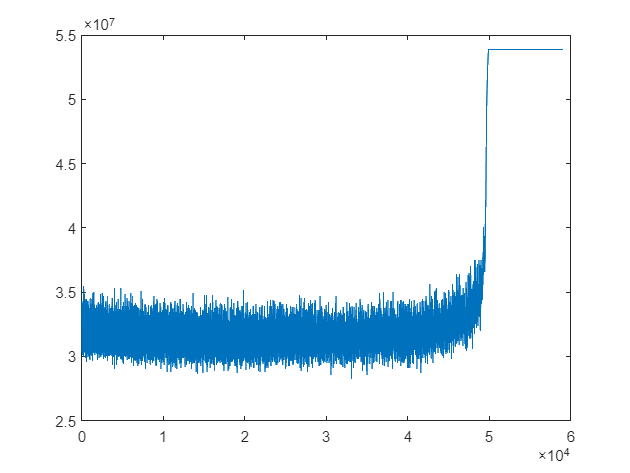

plot(n,R_change,'-')


x1 = x1./sum(x1,2);
x1 = x1.*S;
x1(isnan(x1)) = 0;
writematrix(x1, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2024');

x2 = x2./sum(x2,2);
x2 = x2.*S;
x2(isnan(x2)) = 0;
writematrix(x2, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2025');

x3 = x3./sum(x3,2);
x3 = x3.*S;
x3(isnan(x3)) = 0;
writematrix(x3, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2026');

x4 = x4./sum(x4,2);
x4 = x4.*S;
x4(isnan(x4)) = 0;
writematrix(x4, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2027');

x5 = x5./sum(x5,2);
x5 = x5.*S;
x5(isnan(x5)) = 0;
writematrix(x5, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2028');

x6 = x6./sum(x6,2);
x6 = x6.*S;
x6(isnan(x6)) = 0;
writematrix(x6, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2029');

x7 = x7./sum(x7,2);
x7 = x7.*S;
x7(isnan(x7)) = 0;
writematrix(x7, "E:\数学建模比赛\自处理数据\3随机情况三的结果.xlsx",'Sheet','2030');

% r_D = (rand()+1)*0.05
% randn()*0.003+0.05
% (rand()-0.5)*0.1
% (rand()-0.5)*0.2
% (4*rand()-5)*0.1
% -(randn()*0.003+0.05)
% 
% 10:-1:1
% 
% for i = 1:7
%     r_D1(i) = (rand()+1)*0.05;
% end
% 
% Y_r_D1 = ones(7,7);
% for i = 1:7
%     Y_r_D1(i,7:-1:(8-i)) = r_D1(1:i)+1;
% end
% Y_r_D1
% Y_r_D1 = Y_r_D1(:,1).* Y_r_D1(:,2).*Y_r_D1(:,3).* Y_r_D1(:,4).* Y_r_D1(:,5).* Y_r_D1(:,6).* Y_r_D1(:,7)
% 
% x = rand(82,41);
% x(x<0.9) = 0;
% x(x>=0.9) = 1;
% q = ones(82,41);
% 
% xx = hubu_tiaozheng(x,q);


aa1=1:16;
bb1=17:37;
cc1=38:41;



function [iterations, R_change,R, x1 ,x2 ,x3 ,x4 ,x5 ,x6 ,x7] = sa_tsp(S, x0, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2) 
%A:1~6
%B:7~20
%C:21~26
%D:27~34
%E:35~50
%F:51:54
%D':55~62
%E':63~78
%F':79~82
    % 模拟退火算法参数
    T = 50;         % 初始温度
    T_min = 1e-8;     % 最小温度
    alpha = 0.98;     % 温度衰减率
    maxIterations = 200;  % 每个温度下的迭代次数
    R_change = [];
    iterations = 1;


    % 生成初始解
    % 注，该初始解只是满足基础的种植面积的条件
    x1 = chushijie(1);
    x2 = chushijie(1);
    x3 = chushijie(1);
    x4 = chushijie(1);
    x5 = chushijie(1);
    x6 = chushijie(1);
    x7 = chushijie(1);

    % 对初始解进行调整，满足一块地不能连续两年种植同一种作物
    x1 = tiaozheng1(x0,x1);
    x2 = tiaozheng1(x1,x2);
    x2 = tiaozheng2(x0,x1,x2);
    x3 = tiaozheng1(x2,x3);
    x3 = tiaozheng2(x1,x2,x3);
    x4 = tiaozheng1(x3,x4);
    x4 = tiaozheng2(x2,x3,x4);
    x5 = tiaozheng1(x4,x5);
    x5 = tiaozheng2(x3,x4,x5);
    x6 = tiaozheng1(x5,x6);
    x6 = tiaozheng2(x4,x5,x6);
    x7 = tiaozheng1(x6,x7);
    x7 = tiaozheng2(x5,x6,x7);
    % 对初始解进行调整，满足每块地连续三年必种一次豆类作物
%     x2 = tiaozheng2(x0,x1,x2);
%     x3 = tiaozheng2(x1,x2,x3);
%     x4 = tiaozheng2(x2,x3,x4);
%     x5 = tiaozheng2(x3,x4,x5);
%     x6 = tiaozheng2(x4,x5,x6);
%     x7 = tiaozheng2(x5,x6,x7);

    % 计算初始解的收益
    R1 = calculateR4(x0, x1, 1, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R2 = calculateR4(x1, x2, 2, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R3 = calculateR4(x2, x3, 3, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R4 = calculateR4(x3, x4, 4, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R5 = calculateR4(x4, x5, 5, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R6 = calculateR4(x5, x6, 6, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
    R7 = calculateR4(x6, x7, 7, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);

    R = R1+R2+R3+R4+R5+R6+R7;
    R_change = [R_change R];
    

    % 模拟退火主循环
    while T > T_min
        for i = 1:maxIterations    % 每个温度下的迭代次数
            % 生成新解的第一步，继承部分旧解的特性
            new_x1 = x1;
            new_x2 = x2;
            new_x3 = x3;
            new_x4 = x4;
            new_x5 = x5;
            new_x6 = x6;
            new_x7 = x7;

            %用随机生成的方法更新解
            change = round(T)+18+round(log(T));

            %发生改变的地块
            change_id1 = randperm(82, change);
            new_x1(change_id1,:) = 0;
            new_x1 = gengxin(change_id1,new_x1);

            change_id2 = randperm(82, change);
            new_x2(change_id2,:) = 0;
            new_x2 = gengxin(change_id2,new_x2);     

            change_id3 = randperm(82, change);
            new_x3(change_id3,:) = 0;
            new_x3 = gengxin(change_id3,new_x3);

            change_id4 = randperm(82, change);
            new_x4(change_id4,:) = 0;
            new_x4 = gengxin(change_id4,new_x4);
            
            change_id5 = randperm(82, change);
            new_x5(change_id5,:) = 0;
            new_x5 = gengxin(change_id5,new_x5);

            change_id6 = randperm(82, change);
            new_x6(change_id6,:) = 0;
            new_x6 = gengxin(change_id6,new_x6);

            change_id7 = randperm(82, change);
            new_x7(change_id7,:) = 0;
            new_x7 = gengxin(change_id7,new_x7);
            
            % 对改变后的新解进行调整，使他们满足条件
            new_x1 = tiaozheng1(x0,new_x1);

            new_x2 = tiaozheng1(new_x1,new_x2);
            new_x2 = tiaozheng2(x0,new_x1,new_x2);

            new_x3 = tiaozheng1(new_x2,new_x3);
            new_x3 = tiaozheng2(new_x1,new_x2,new_x3);

            new_x4 = tiaozheng1(new_x3,new_x4);
            new_x4 = tiaozheng2(new_x2,new_x3,new_x4);

            new_x5 = tiaozheng1(new_x4,new_x5);
            new_x5 = tiaozheng2(new_x3,new_x4,new_x5);

            new_x6 = tiaozheng1(new_x5,new_x6);
            new_x6 = tiaozheng2(new_x4,new_x5,new_x6);

            new_x7 = tiaozheng1(new_x6,new_x7);
            new_x7 = tiaozheng2(new_x5,new_x6,new_x7);
            

            % 计算新解的总收益
            new_R1 = calculateR4(x0, new_x1, 1, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R2 = calculateR4(new_x1, new_x2, 2, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R3 = calculateR4(new_x2, new_x3, 3, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R4 = calculateR4(new_x3, new_x4, 4, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R5 = calculateR4(new_x4, new_x5, 5, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R6 = calculateR4(new_x5, new_x6, 6, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);
            new_R7 = calculateR4(new_x6, new_x7, 7, S, P, D, q, C, Y_r_D1, Y_r_D2, Y_r_q, Y_r_C1, Y_r_C2, Y_r_P1, Y_r_P2);

            new_R = new_R1 + new_R2 + new_R3 + new_R4 + new_R5 + new_R6 + new_R7;


            % 接受新解的概率
            if  any([new_R >= R ,exp((new_R - R) / (T*R/(20+log(T)))) > rand()])     %all([newDistance0 < 144 ,  any([currentscore0 <= newscore0, exp(-(currentscore0 - newscore0) / T) > rand()])])
                x1 = new_x1;
                x2 = new_x2;
                x3 = new_x3;
                x4 = new_x4;
                x5 = new_x5;
                x6 = new_x6;
                x7 = new_x7;
                R = new_R;
                R_change = [R_change R];
                iterations = iterations+1;

            end
        end
        % 降低温度
        T = T * alpha;
    end

disp('---------------------------------------------------------------')
iterations;
end


function R = calculateR(xxx ,S, P, D, q, C)
xxx = xxx./sum(xxx,2);
Q1 = xxx.*S;
Q1(isnan(Q1)) = 0;
Q_1(1,:) = sum(Q1(1:6,:));
Q_1(2,:) = sum(Q1(7:20,:));
Q_1(3,:) = sum(Q1(21:26,:));
Q_1(4,:) = sum(Q1(27:34,:));
Q_1(5,:) = sum(Q1(35:50,:));
Q_1(6,:) = sum(Q1(51:54,:));
Q_1(7,:) = sum(Q1(55:62,:));
Q_1(8,:) = sum(Q1(63:78,:));
Q_1(9,:) = sum(Q1(79:82,:));

Q_11 = Q_1.*q;

R = sum(P.*min(Q_11,D) - C.*Q_1, "all");
end

% 对初始解进行调整，满足一块地不能连续两年种植同一种作物
function x = tiaozheng1(x0,x1)
[r,c] = find(x0~=0);
for i = 1:length(r)
    x1(r(i),c(i)) = 0;
end
x = x1;
end



